# Graphics and Data Visualization

## Graphic Handles

#### Graphics objects

- Basic drawing elements used by MATLAB to display data

- Each object instance has unique identifier, *handle*

- Graphics objects behave like other MATLAB objects.

- Objects organized in hierarchy

#### **Organization of Graphics Objects**

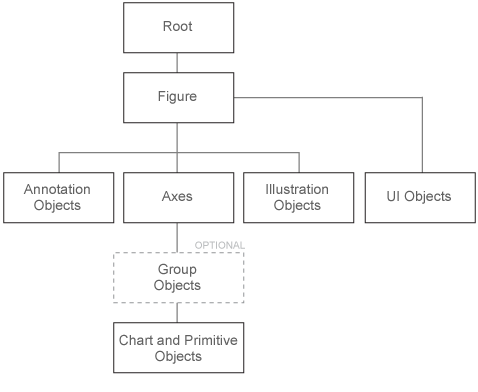

**Core graphics object**

- `axes, image, line, patch, rectangle, surface`

**Composite graphics object**

- Plot objects: `areaseries, barseries, contourgroup, errorbarseries, lineseries, quivergroup, scattergroup, staircase, stemseries, surfaceplot`

- Annotation objects: `arrow, doublearrow, ellipse, line, rectangle, textarrow, textbox`

- Group objects: `hggroup, hgtransform`

- User Interface objects

### Graphics Handle

A **handle** refers to a specific instance of a graphics object. We use the object handle to set and query the values of the object properties.

1. Obtain graphics handle from the call that creates the graphics object:

`figH = figure('pos',[141,258,869,523]);`

`axH = axes();`

`ax1H = subplot(2,2,3);`

`sinH = plot(sin(linspace(0,2*pi,100)));`

`[c,contH] = contour(peaks);`

2. Use object hierarchy to get handles to Parent/Children objects:

`sinH = plot(sin(linspace(0,2*pi,100)))`

`ax=sinH.Parent`

`fig=ax.Parent`

3. Select figure/axes/object of interest manually with mouse or use `gcf` (handle of current figure),` gca `(handle of current axes),` gco` (handle of current object)`.`

To check if an object is a graphic handle use `isgraphics`.

Preallocate arrays of graphics handles using the `gobjects` function (itialize array for graphics objects).

`get` - Query values of object's properties

`set` - Set values of an object's properties

#### Specifying Figure or Axes to Use

Specify figure in which to create new axes object

fHan = gobjects(3,1);
for i = 1:3, fHan(i)=figure(); end
ax = axes('Parent',fHan(2))

Specify axes in which to create new graphics object

- Most, if not all, plotting commands accept an axes handle as the *first* argument

- Graphics object is generated in axes object corresponding to handle passed

- If axes handle not specified, `gca` is used

% peaks gives the z-coordinates of the peaks function over a 49-by-49 grid.
[C,objHan] = contourf(ax,peaks)

ax = gca(fHan(1)); % gca creates axes if not defined
[C,objHan] = contourf(ax,peaks.^2)

`...`

close all

**Demo of graphic handles**

x = 0:0.01:10;
y = x.^4-x.^2.*sin(x);

p = plot(x,y); % line
p
ax = p.Parent; % axis
ax
f = ax.Parent; % figure
f
ax.FontSize
f.Position

figH = figure('Position',[141,258,869,523]);
axes() % create default cartesian axes
ax1H = subplot(2,2,3);
ax2H = subplot(2,2,4);
figH.Children
sinH = plot(ax1H,sin(linspace(0,2*pi,100)))

**Quiz.**

Run this piece of code and see what happens. 

figure; axes(); hold on 
x = linspace(0,2*pi,100);
for k = 1:10
    plot(x,sin(k*x));
end
hold off

Modify the piece of code such that `sin(k*x)` is plotted versus x for even k's in one single figure, and for odd k's in another figure.


title(aH(2),"odd");

### Working with Graphics Objects

#### 2 ways to access/modify object properties

Use dot notation to refer to a particular object and property. Property names are case sensitive when using dot notation. 

figure; h = plot(1:10); h.Color = 'red';

Use the `set`** and **`get`** functions** to access properties for an array of objects.

- `set(han,s) %s structure `Set property-value pairs from

- `set(han,pn,pv)%pn, pv cell arrays `Set value of property `pn{i}` to `pv{i}`

- `V = get(han) `Store all properties-value pairs in structure V

- `V = get(han,'Property') `Store Property value in V

x=-10:0.1:10; y=[sin(x);cos(x)]; 
h=plot(x,y);  
set(h,'LineWidth',2); 
get(h,'LineWidth')
V = get(h)

**Modify multiple properties for an array of objects**

x = 0:30;
y = [1.5*cos(x); 4*exp(-.1*x).*cos(x); exp(.05*x).*cos(x)]';
% plots the data sequence Y at the values specified in X.
S = stem(x,y);

NameArray = {'Marker','Tag'};
ValueArray = {'*','Steady State';'o','Decaying Exponential';...
'square','Growing Exponential'};
set(S,NameArray,ValueArray);
findobj('Tag','Growing Exponential')

#### Property inspector 

Launch the property inspector, and look at all the different properties of the graphical object.

close all; clear; clc

### Properties of Figure, Axes, and Plot Objects

**Figure window**

- Object name in command prompt to see all properties of Figure object and defaults

- `Colormap, Position, PaperPositionMode`

**Axes Object**

- Axes objects contain the lines, surfaces, and other objects that represent the data visualized in a graph

- Object name in command prompt to see all properties of Axes object and defaults

- `XLim, YLim, ZLim, CLim, XGrid, YGrid, ZGrid, XTick, XTickLabel, YTick, YTickLabel, ZTick, ZTickLabel, XScale, YScale, ZScale`

**Plot Objects**

- Plot objects are composite graphics objects composed of one or more core objects in a group

- `XData, YData, ZData, Color, LineStyle, LineWidth`

#### Properties Common to All Objects

`Parent, Children, BeingDeleted (on` when object's `DeleteFcn` is called`), DeleteFcn (`Callback rountine that excutes when object is deleted`), CreateFcn, Selected,` `Visible`, etc.

### Legend

**typical syntax**

`legend('First plotted','Second plotted','Location','Northwest')`

**use handles for fine-grained control**

`legend(han,'han(1)label','han(2)label','Location','Northwest')`

**legend handdle**

get the handle by` leg = legend()`

use handel to control size/location (more control than `'Location'`), font size/style, line style, etc.

#### Demo

figure;
axes(); hold on;
x = linspace(0,2*pi,1000);
for k = 1:3
    plot(x,sin(k*x));
end
% initialize a legend at lower-right corner
leg = legend('k=1','k=2','k=3','Location','Southeast')

Fine control using handle:

move it to the upper-right corner and make it larger

set(leg,'Location','northeast','FontSize',18, 'LineWidth',2)

### Callback Routines

Function associated with graphics handle that gets called in response to a specific action applied to the associated graphics object

- Object creation, deletion

- Mouse motion, mouse press, mouse release, scroll wheel

- Key press, key release

All callback routines are automatically passed two inputs

- Handle of component whose callback is being executed

- Event data

Callback routines specified in many possible forms

- String: expression evaluated in base workspace

- Function handle

- Cell arrays to pass additional arguments to callback routine

#### Example

**Callback creation**

set(0,'DefaultFigureCreateFcn','disp(''Hello world!!'')');

**Generate objects and get handles**

fig = figure();
ax(1) = subplot(1,2,1); % axes generated in current figure
ax(2) = subplot(1,2,2,'Parent',fig); % axes generated in fig
x = linspace(0,2,20);
o1 = plot(x,exp(x)); % plot in current axes
[~,o2] = contour(ax(1),peaks); % plot in specified axis
set(ax(2),'nextplot','add'); % equivalent to hold on
o3 = plot(ax(2),x,exp(2*x));

% Callback
set(o1,'DeleteFcn','disp(''Goodbye cruel world!!'')');
set(o2,'DeleteFcn','disp(''O2 is gone!!'')');
set(o3,'DeleteFcn','disp(''Bye, O3!!'')');

**Make the figure prettier**

% Resize figure 
fig.Position=[440   205   833   573];
% Use log scale on y-axis for ax(2)
ax(2).YScale='log';
set(ax(2),'yminorgrid','on','ygrid','on','xgrid','on');
% Reverse direction of x-axis (descending) for ax(2)
ax(2).XDir='reverse';
% Remove ticks and labels from ax(1)
set(ax(1),'xtick',[],'ytick',[]);
% Change colormap on ax(1) to bone
colormap(ax(1), bone);
% For object o2, change lines to dashed
o2.LineStyle='--';
% For object o1, make line thick and dashed-dotted
set(o1,'linewidth',2,'linestyle','-.');
% For object o3, use o markers with faces of color [0.8,0.8,0.8] and black edges
set(o3,'marker','o','markerfacecolor',[0.8,0.8,0.8],'markeredgecolor','k');
% Add xlabel ('first x') to ax(1) with size 16 font  ('FontSize')
xlbl = xlabel(ax(1),'first x','fontsize',16); 
% Add ylabel ('second y') to ax(2) in the color blue ('Color')
ylbl = ylabel(ax(2),'second y','color','b');
% Add title to ('Contour plot') to ax(1) in font Time  ('FontName')
ti(1) = title(ax(1),'Contour plot','fontname','times');
% Add legend to ax(1) to label the two lines
leg = legend([o3,o1],'$exp(2x)$','$exp(x)$');
leg.Interpreter='latex';

close(fig)

% Reset root!
set(0,'DefaultFigureCreateFcn',[]);

## Advanced Plotting

close all; clear; clc

### Line plots

#### `yyaxis` (formerly plotyy)

plot two graphs with different y axes

x=0:0.1:10;
y1 = 200*exp(-0.05*x).*sin(x);
y2 = 0.8*exp(-0.5*x).*sin(10*x);
figure;
yyaxis left
plot(x,y1);
yyaxis right
stem(x,y2);

#### `errorbar` plot

Line plot with error bars

figure;% errorbar
x = linspace(0,pi,10);
y = sin(x);
l = std(y)*ones(size(x)).*randn(size(x));
u = std(y)*ones(size(x)).*randn(size(x));

%set convenient for modifying multiple properties at once
hE = errorbar(x,y,l,u);
set(hE                            , ...
  'LineStyle',        'none'      , ...
  'LineWidth'       , 1           , ...
  'Color'           , [.3 .3 .3]  , ...
  'Marker'          , 'o'         , ...
  'MarkerSize'      , 6           , ...
  'MarkerEdgeColor' , [.2 .2 .2]  , ...
  'MarkerFaceColor' , [.7 .7 .7]  );

Other commands:

- `plot` 2D line plot

- `yyaxis` 2D line plot, y-axes both sides

- `plot3` 3D line plot

- `loglog` 2D line plot: x- and y-axis log scale

- `semilogx` 2D line plot, x-axis log, y-axis linear

- `semilogy` 2D line plot, x-axis linear, y-axis log

- `errorbar` Error bars along 2D line plot

- `fplot` Function plotter (plots the function FUN between the limits of the current axes)

- `fplot3` 2D parametric curve plotter

fplot(@sin,[-2,2])

#### `bar` and `histogram` plots

X = randn(1000,1);
Y = round(rand(5,3)*10);

figure;
ax(1) = subplot(2,2,1);
histogram(X); title('histogram');
ax(2) = subplot(2,2,3);
bar(1:5,Y); title('bar');
ax(3) = subplot(2,2,4);
barh(1:5,Y,'stacked'); title('barh');

#### Pie plot

figure;
pie3([12,1,2],[0,1,0],{'Work','Fun (CME292)','Sleep'});
title('Life of a Graduate Student');

Other commands:

- `bar, barh` Vertical, horizontal bar graph

- `bar3, bar3h` Vertical, horizontal 3D bar graph

- `histogram` Histogram

- `histcounts` Histogram bin count (no plot)

- `polarhistogram` Histogram in polar coordinates

- `pareto` Pareto chart

- `area` Filled area 2D plot

- `pie, pie3` 2D, 3D pie chart

pareto([0.3,0.2,0.1,0.4],{'frac1','frac2','frac3','frac4'})

#### Scatter plot

% Discrete data example
figure
load seamount
s = linspace(1,30,length(x));
c = linspace(1,10,length(x));
scatter(x,y,s,c)

#### Polygon plots

`patch(X,Y,C)` creates one or more filled polygons

To create multiple polygons, specify X and Y as matrices where each column corresponds to a polygon. C determines the polygon colors.

xdata = [2     2     0     2     5;
         2     8     2     4     5;
         8     8     2     4     8];
ydata = [4     4     4     2     0;
         8     4     6     2     2;
         4     0     4     0     0];
cdata = [15     0     4     6    10;
         1     2     5     7     9;
         2     3     10     8     3];
figure;
%you can also edit line properties when creating the object
p = patch(xdata,ydata,cdata,'Marker','o',...
          'MarkerFaceColor','flat',...
          'FaceColor','interp');

### 2D plots 

#### `recall: grid data`

x = linspace(-2*pi,2*pi);
y = linspace(0,4*pi);
[X,Y] = meshgrid(x,y);

#### `contour` plot examples

Z = sin(X)+cos(Y);
figure('pos',[241,246,1041,269]);
subplot(1,3,1); contour(X,Y,Z,10); title('contour (20)');
subplot(1,3,2); contourf(X,Y,Z,20); title('contourf (20)');
subplot(1,3,3); contour3(X,Y,Z,20); title('contour3 (20)');

close all
figure('pos',[241,246,1041,269]);
v = logspace(-5,log10(max(Z(:))),10);
v = [-fliplr(v),0,v];
% draw a contour line for each level specified in vector V
subplot(1,3,1); contour(X,Y,Z,v); title('contour (v)');
subplot(1,3,2); contourf(X,Y,Z,v); title('contourf (v)');
subplot(1,3,3); contour3(X,Y,Z,v); title('contour3 (v)');

Other commands:

- `contour` Contour plot

- `contourf` Filled contour plot

- `contourc` Contour plot computation (no plot)

- `contour3` 3D contour plot

- `contourslice` Draw contours in volume slice planes

- `fcontour` Contour plotter

#### `surface` and `mesh` plots

% Surface and mesh plot examples
x = linspace(-2*pi,2*pi,40);
y = linspace(0,4*pi,40);
[X,Y] = meshgrid(x,y);
Z = sin(X)+cos(Y);

figure('pos',[21,22,1402,762]);
subplot(2,3,1); surf(X,Y,Z); title('surf'); axis equal;
subplot(2,3,2); surfc(X,Y,Z); title('surfc'); axis equal;
subplot(2,3,3); waterfall(X,Y,Z); title('waterfall'); axis equal;

subplot(2,3,4); mesh(X,Y,Z); title('mesh'); axis equal;
subplot(2,3,5); meshc(X,Y,Z); title('meshc'); axis equal;

A **surface normal** is the imaginary line perpendicular to a flat surface, or perpendicular to the tangent plane at a point on a non-flat surface.

figure('pos',[12,22,1402,762]);
surfnorm(X,Y,Z); title('surfnorm'); axis equal;

Other commands:

- `surf` 3D shaded surface plot

- `surfc` Contour plot under surf plot

- `surfl` Surface plot with colormap lighting

- `surfnorm` Compute/plot 3D surface normals

- `mesh` Mesh plot

- `meshc` Contour plot under mesh plot

- `waterfall` Waterfall plot

- `ribbon` Ribbon plot

- `fsurf` Colored surface plotter

- `fmesh` Mesh plotter

close all; clear; clc

### Vector fields

#### `quiver `plot

plot velocity vectors from specified points


[X,Y] = meshgrid(-2:.2:2);
Z = X.*exp(-X.^2 - Y.^2);
[DX,DY] = gradient(Z,.2,.2);

figure;
contour(X,Y,Z);
hold on
quiver(X,Y,DX,DY);
hold off;

#### `streamline `plot

[x,y] = meshgrid(0:0.1:1,0:0.1:1);
u = x;
v = -y;

figure;
quiver(x,y,u,v);

startx = 0.1:0.1:1; % x=0.1,0.2,...
starty = ones(size(startx)); % y=1
sH = streamline(x,y,u,v,startx,starty);
set(sH,'Color','red')

Other commands:

- `feather` Plot velocity vectors along horizontal, useful for displaying direction and magnitude data that is collected along a path

- `quiver, quiver3 `Plot 2D, 3D velocity vectors from specified points

- `compass` Plot arrows emanating from origin

- `streamslice` Plot streamlines in slice planes

- `streamline` Plot streamlines of 2D, 3D vector data

u = linspace(0,10,21);
feather(sin(u),cos(u)), axis equal

**Quiz.**

s = linspace(0,2*pi,20);
[X,Y] = meshgrid(s,s);
F = sin(X.*Y);
v = -1:0.25:1; % levels

Plot the filled contour plot using X, Y, F, v. Use colormap spring, or autumn. You may also try others.

Compute the gradient and plot the vector field on the same figure.

Add streamline starting at x=2, y=2, and x=5, y=5. Set line color to white, line width to 3.

close all; clear; clc

### Volume visualizations of scalar data

`flow` produces fluid flow data that is useful for demonstrating volumne visualizations.

[x,y,z,f] = flow(10); % N-by-2N-by-N array

#### `contourslice`

`xslice`, `yslice`, and `zslice` are the slice locations, where we draw one or more slice planes that are orthogonal to a particular axis, specified by the slice arguments as a scalar or vector.

figure; colormap jet
sl=contourslice(x,y,z,f,1:9,[-1.0,1.0],0.0); colorbar
ax=sl.Parent;
ax.CameraPosition=[29.6363 35.2805 31.9907];

####  `slice`

figure; colormap jet
sl=slice(x,y,z,f,[1,9],[-1.0,1.0],0.0);
ax=sl.Parent;
ax.CameraPosition=[-29.6363 -35.2805 31.9907];

#### iso plots:` isocap, isocolors, isonormals, isosurface`

An **isosurface** is a 3-D surface representation of points with equal values in a 3-D data distribution. The `isosurface` function computes and draws a surface by connecting points of a constant value within a volume of space.

`isosurface(X,Y,Z,V,ISOVALUE,COLORS)` computes isosurface geometry for data `V` at isosurface value `ISOVALUE` and interpolates the array `COLORS` onto the scalar field.

figure; colormap jet
isosurface(x,y,z,f,0.0,sqrt(x.^2+y.^2+z.^2));
ax=gca;
ax.CameraPosition=[-29.6363 -35.2805 31.9907];

Other commands:

- `contourslice` Draw contours in volume slice planes

- `flow` Simple function of three variables

- `isocaps` Compute isosurface end-cap geometry

- `isocolors` Compute isosurface and patch colors

- `isonormals `Compute normals of isosurface vertices

- `isosurface `Extract isosurface data from volume data

- `slice` Volumetric slice plot

close all; clear; clc

## Volume visualizations of vector data

Data `wind`: air currents over regions of North America.

load wind
figure
streamslice(x,y,z,u,v,w,[],[],10)
axis tight

[sx,sy,sz] = meshgrid(80,20:10:50,0:5:15);
close all;
figure
streamline(stream3(x,y,z,u,v,w,sx,sy,sz));view(3);

`streamtube`

`streamtube(X,Y,Z,U,V,W,startx,starty,startz)`

`startx,starty,startz` define the starting positions of the streamlines at the center of the tubes. The width of the tubes is proportional to the normalized divergence of the vector field.

close all;
f_st = figure(); colormap jet
streamtube(x,y,z,u,v,w,sx,sy,sz);
view(3);
axis tight
shading interp;
camlight; lighting gouraud

Use vertex data and divergence:

`streamtube(VERTICES,X,Y,Z,DIVERGENCE)` assumes precomputed streamline vertices and divergence. `VERTICES` is cell array of streamline vertices (as if produced by stream3). `X,Y,Z`, and `DIVERGENCE` are 3D arrays

f_st = figure(); colormap jet
div = divergence(x,y,z,u,v,w);
verts = stream3(x,y,z,u,v,w,sx,sy,sz);
streamtube(verts,x,y,z,div);
view(3);
axis tight
shading flat;
camlight; lighting flat

Other commands:

- `coneplot` Plot velocity vectors as cone

- `interpstreamspeed `Interpolate stream-line vertices from flow speed

- `stream2, stream3` Compute 2D, 3D streamline data

- `streamline` Plot streamlines of 2D, 3D vector data

- `streamparticles` Plot stream particles

- `streamribbon` 3D stream ribbon plot

- `streamslice` Plot streamlines in slice planes

- `streamtube` Create 3D stream tube plot

## Generate plots for publications using MATLAB

Generate plots in MATLAB and import into document

- Graphics handles to deal with aesthetics

Generate data in MATLAB and plot in document

- TikZ/PGF (popular choice for LATEX)

Hybrid (`matlab2tikz`)

Generate plot with all lines/labels/annotations/legends/etc

Set properties (graphics handles or interactively)

- Figure width/height

- Axes line width, object line width, marker size

- Font sizes

Save figure to file

- WYSIWYG: '`PaperPositionMode`' is '`auto`' by default

- Print to file for inclusion in document: `print(gcf,'-depsc2',filename); matlab2tikz(filename)`

## Example

Let's reuse the streamtube plot.

set(f_st,'PaperOrientation','landscape');
print(f_st,'-dpdf','wind')

close all; clear; clc

## Animation

**Interactive animation**: *Generate and display animation during execution of code*

**Animation movies: ***Save animation in movie format*

Generated by calling plot commands inside a loop with new data generated at each iteration

Before entering loop

- Create figure and axes

- Modify object using handles to achieve desired appearance

- Use command `set(gca,'nextplot','replacechildren')` to ensure only children of axes object will be replaced upon next plot command (will not modify axes properties)

During loop

- Plot command to generate data on plot

- Modify object using handle to achieve desired appearance

- Use command `drawnow` to draw object, otherwise it will not be drawn until execution is complete (MATLAB optimization, as plotting is expensive)

Alternatively, modify XData, YData, ZData properties of initial plot object

Additionally, save sequence of plotting command as frames (getframe) and play back from MATLAB window (movie)

**Demo.**

`option = 1` creates an animation by manipulation the data property of the line objects.

`option = 2` is the animation re-created by plotting inside the FOR loop. 

close all; clear; clc

option = 1;
n_loops = 50;
% Preallocate array to store the movie frames
M(n_loops) = struct('cdata',[],'colormap',[]); 

tic
fig = figure();
ax  = axes();

x = linspace(0,5*pi,n_loops);
y = sin(x);

switch option
    case 1
        %Option 1
        o1 = plot(x(1),y(1),'o','MarkerEdgeColor','k','MarkerFaceColor',[0.8,0.8,0.8],'MarkerSize',10); 
        hold on
        o2 = plot(x(1),y(1),'k-','LineWidth',2);
        o3 = plot(x(1),y(1),'o','MarkerEdgeColor','k','MarkerFaceColor','b','MarkerSize',10);
        
        ax.XLim = [min(x),max(x)];
        ax.YLim = 2*[min(y),max(y)];
        
        hold off
        
        for i = 1:length(x)
            o1.XData = x(i);
            o1.YData = y(i);
            o2.XData = x(1:i);
            o2.YData = y(1:i);
            o3.XData = x(i)-2*pi;
            o3.YData = y(i);

            drawnow;
            M(i) = getframe;
        end
    case 2
        %Option 2
        for i = 1:length(x)
            plot(x(i),y(i),'o','MarkerEdgeColor','k','MarkerFaceColor',[0.8,0.8,0.8],'MarkerSize',10); 
            hold on
            plot(x(1:i),y(1:i),'k-','LineWidth',2);
            plot(x(i)-2*pi,y(i),'o','MarkerEdgeColor','k','MarkerFaceColor','b','MarkerSize',10);
            
            ax.XLim = [min(x),max(x)];
            ax.YLim = 2*[min(y),max(y)];
            
            hold off
            drawnow;
            M(i) = getframe;
        end
end
toc
movie(M)

You may also create a video file from a MATLAB movie. Check out this page: [https://www.mathworks.com/help/matlab/ref/videowriter.html](https://www.mathworks.com/help/matlab/ref/videowriter.html). 